# DATA 10: **Single Nucleotide Polymorphism (SNP)**

% SNP (Single Nucleotide Polymorphism) is a single-base variation (A, T, C, G) 
% at a specific genomic position where different individuals carry different 
% nucleotides. SNPs represent common genetic variation across a population and are
% widely used to study ancestry, population structure, and disease risk. Each SNP 
% acts as a feature, forming a high-dimensional genetic space where individuals 
% can be compared geometrically.
%
% File contains Variant Call Format (VCF) file from the Phase 3 release of the 1000
% Genomes Project. It contains all high-quality small genetic variants (SNPs and short 
% indels) identified on human chromosome 22 across 2,504 individuals from 26 worldwide 
% populations.
%
% Chromosome 22 is commonly used in methodological and teaching settings because 
% it is one of the smallest human autosomes (~51 million base pairs) while still 
% containing dense and representative SNP variation. It preserves global population 
% structure (e.g., AFR/EUR/EAS separation) and realistic linkage disequilibrium 
% patterns, yet remains computationally manageable compared to the full genome. 
% Since population structure is genome-wide, a single chromosome is sufficient to 
% recover meaningful genetic geometry, making chromosome 22 a practical balance 
% between biological relevance and computational feasibility.
%
% The data is published in
%
%@article{10002010map,
%  title={A map of human genome variation from population scale sequencing},
%  author={1000 Genomes Project Consortium and others},
%  journal={Nature},
%  volume={467},
%  number={7319},
%  pages={1061},
%  year={2010}
%}
%
% If you are using this data, cite the paper. 
%[POS, REF, ALT, X, samples] = vcf_load_subset('chr22.genotypes.vcf', 100000);
%save SNP-chromosome22 POS REF ALT X samples

load SNP-chromosome22

% Variables in the dataset consists of 
%
%   m = 10000, number of variants (SNP locations) loaded from the VCF file.
%       Each row i corresponds to one genomic position POS(i) on chr22.
%
%   n = 2504, number of subjects (individuals) in the dataset.
%       Each column j corresponds to one sample ID in "samples".
%
%   POS     : [m x 1] genomic coordinates on chromosome 22 
%                    (reference genome coordinate system)
%   REF     : [m x 1] cell array of reference alleles at each POS(i)
%   ALT     : [m x 1] cell array of alternate alleles observed in the population at 
%             each POS(i)
%
%   X       : [m x n] allele-count (dosage) matrix, entries in {0,1,2}. 
%             Each entry X(i,j) records how many copies of the alternate allele subject 
%             j carries at variant i.
%             An allele-count (dosage) matrix is simply a table that records, 
%             for each genetic position where variation exists and for each person 
%             in the study, how many copies of a particular DNA variant they carry. 
%             Because humans have two copies of each chromosome, the value at each 
%             entry is 0, 1, or 2: 0 means the person carries no copies of the 
%             alternate variant (both DNA copies match the reference), 1 means they 
%             carry one copy of the variant, and 2 means they carry two copies. 
%             Instead of storing DNA letters like A or G directly, this matrix stores 
%             counts of how much each individual differs from the reference genome at 
%             many variant positions, forming a structured numeric summary of genetic 
%             variation across the population.
%
%   samples : [1 x n] sample IDs (each corresponds to one subject / one column of X)


POS(1) 

ans = 16050075

REF(1)

ans = 1×1 cell array
    {'A'}


ALT(1)

ans = 1×1 cell array
    {'G'}


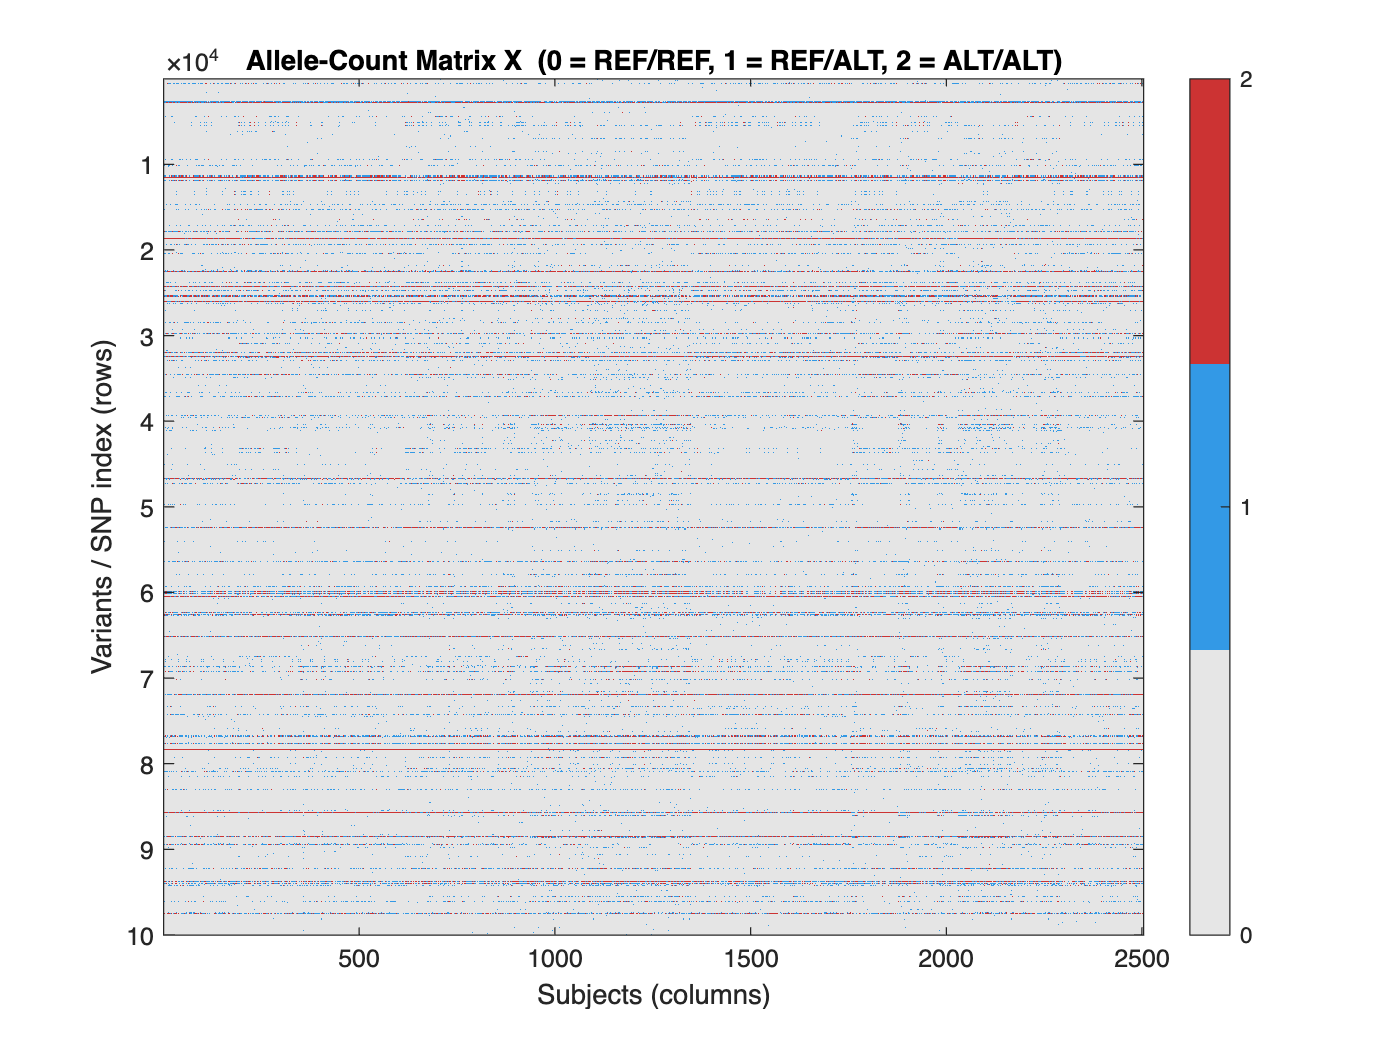

% Display allele-count matrix X with axis labels and integer color bins
figure; imagesc(X);

xlabel('Subjects (columns)');
ylabel('Variants / SNP index (rows)');
title('Allele-Count Matrix X  (0 = REF/REF, 1 = REF/ALT, 2 = ALT/ALT)');

% ---- integer color bins (0,1,2) ----
colormap([0.9 0.9 0.9;    % 0 -> light gray
          0.2 0.6 0.9;    % 1 -> blue
          0.8 0.2 0.2]);  % 2 -> red
colorbar('Ticks',[0 1 2]);

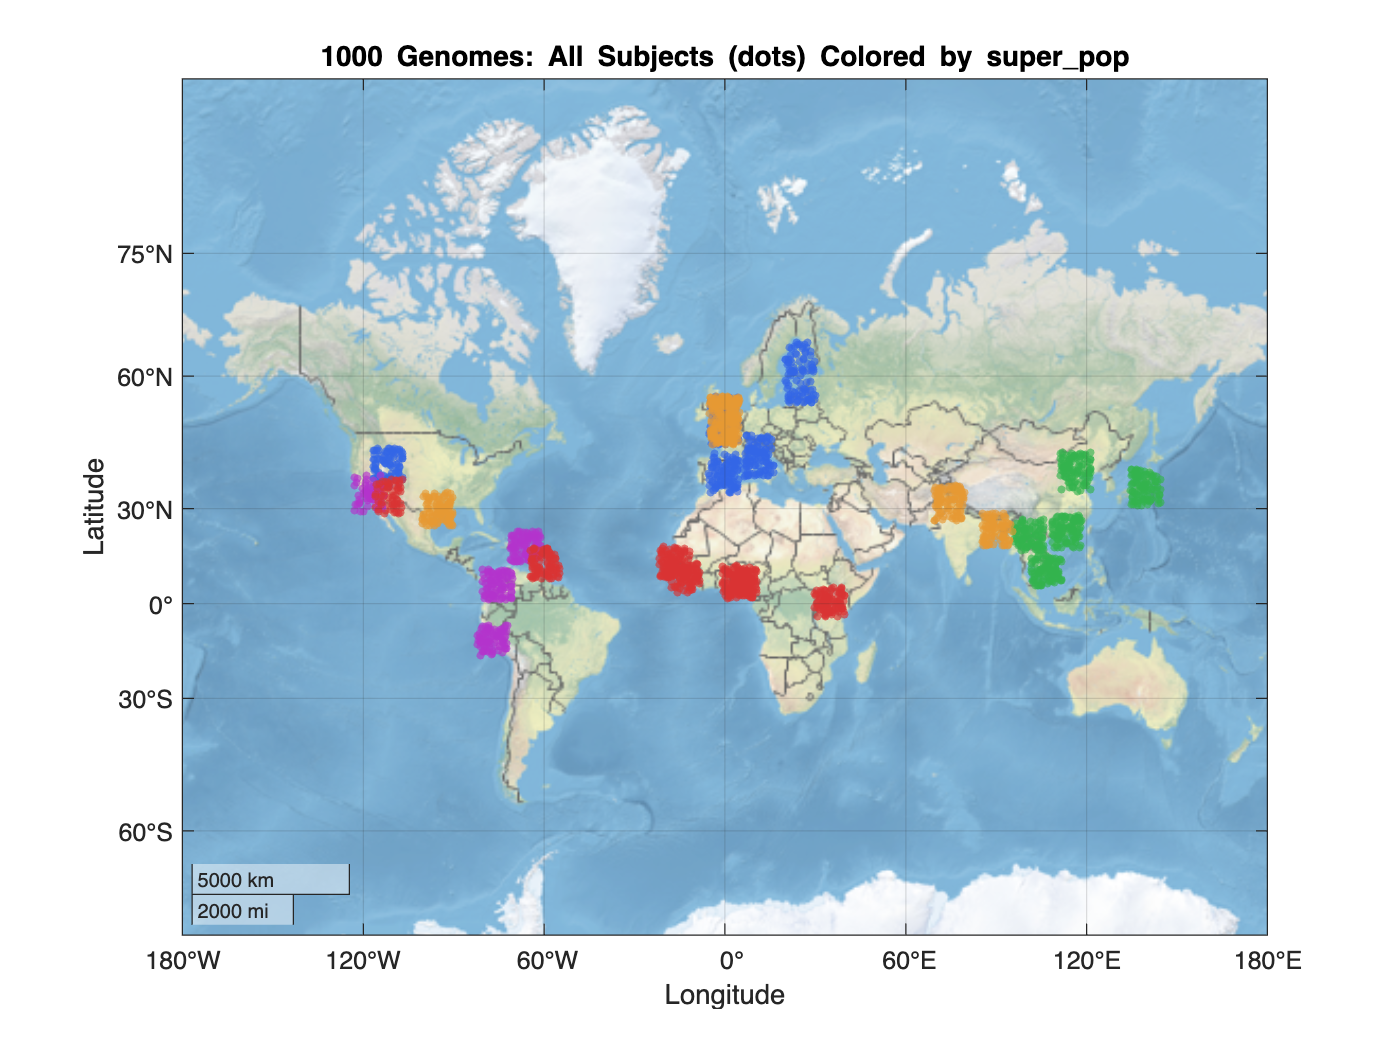

  Value    Count   Percent
    EUR      503     20.09%
    EAS      504     20.13%
    AMR      347     13.86%
    SAS      489     19.53%
    AFR      661     26.40%


% Ground truth labels

T = readtable('geography.panel','FileType','text','Delimiter','\t');
T.Properties.VariableNames;

%   Table T contains
%   sample     : individual ID (matches VCF sample columns)
%   pop        : population code (e.g., GBR, YRI, CHB)
%   super_pop  : continental group (AFR, EUR, EAS, AMR, SAS)
%   gender     : biological sex
%
%      sample         pop      super_pop      gender  
%    {'HG00096'}    {'GBR'}     {'EUR'}     {'male'  }
%    {'HG00097'}    {'GBR'}     {'EUR'}     {'female'}
%    {'HG00099'}    {'GBR'}     {'EUR'}     {'female'}

vcf_display_earth('geography.panel')

## PROJECT 16: Geometric & Topological Analysis of Human SNP Variation

% Goal: Treat each subject as a point in a high-dimensional SNP space and 
% use geometric/topological summaries to recover and quantify population
% structure (AFR/EUR/EAS/AMR/SAS) without using labels in construction.
%
% Discription: This project analyzes human genetic variation from the 
% 1000 Genomes chromosome 22 dataset using geometric and topological 
% data analysis. The data are represented as an allele-count matrix X(i,j), 
% where each entry records how many copies of the alternate allele subject 
% j carries at variant i. Students will construct a meaningful genetic distance,
% define an appropriate inner product, and interpret the data as a metric
% (Hilbert) space in which each subject is a point in high-dimensional SNP
% space. They will analyze the induced geometric structure through
% embeddings and spectral or distance-based geometric methods.
%
% In the second part, students will construct graphs or simplical complex 
% data structrue from the metric space, define monotone filtrations over
% distance or graph parameters, and perform topological data analysis on
% the resulting multiscale structures. Persistent connected components and
% other monotone topological features will be used to quantify clustering
% and separation among continental ancestry groups (AFR, EUR, EAS, SAS, AMR),
% without using population labels in the construction stage.
%
% The primary objective in both geometric and topological analyses is to
% recover and quantitatively characterize population structure purely from
% the intrinsic geometry of the genetic data.
%
% Learning Outcome:  Students will learn how to translate large-scale SNP 
% genotype data into a high-dimensional geometric object in which each 
% subject is represented as a point in a metric (Hilbert) space derived 
% from allele-count variation. They will construct and justify genetic distance 
% measures and inner products, analyze geometric structure through embeddings 
% and spectral methods, and build multiscale graph or simplicial complex 
% filtrations to extract persistent topological features. By evaluating robustness 
% under subsampling of variants and subjects, students will develop a rigorous and
% reproducible MATLAB pipeline and gain a principled understanding of how
% intrinsic genetic variation induces measurable geometric and topological
% structure without relying on population labels.
